# Perfil cinemático del motor

## Perfil cinemático del eje

clear
clc

syms a1(t) a2(t) a3(t) a4(t) a5(t)  T A
syms v1(t) v2(t) v3(t) v4(t) v5(t)  
syms x1(t) x2(t) x3(t) x4(t) x5(t) 

assume(T>0)
assume(A>0)

A=5;


## Aceleración

a1(t)=3*A/T*t;
a2(t)=A;
a3(t)=-3*A/T*t;
Ca3=A-a3(2*T/3);
a3(t)=a3(t)+Ca3;
a4(t)=0;
fprintf('Función de aceleración:')

Función de aceleración:

aceleracion(t)=piecewise((0<=t<T/3),a1,(T/3<=t<2*T/3),a2,(2*T/3<=t<T),a3,(T<=t),a4)

$$aceleracion(t) = \left\{ \begin{array}{cl} \frac{15\,t}{T} & \text{ if }3\,t<T\wedge 0\leq t\\ 5 & \text{ if }T\leq 3\,t\wedge 3\,t<2\,T\\ 15-\frac{15\,t}{T} & \text{ if }t<T\wedge 2\,T\leq 3\,t\\ 0 & \text{ if }T\leq t \end{array}\right.$$

## Velocidad


v1(t)=int(a1)

$$v1(t) = \frac{15\,t^{2}}{2\,T}$$


v2(t)=int(a2);
Cv2=v1(T/3)-v2(T/3);
v2(t)=v2(t)+Cv2

$$v2(t) = 5\,t-\frac{5\,T}{6}$$


v3(t)=int(a3);
Cv3=v2(2*T/3)-v3(2*T/3);
v3(t)=v3(t)+Cv3

$$v3(t) = 15\,t-\frac{25\,T}{6}-\frac{15\,t^{2}}{2\,T}$$


v4(t)=int(a4);
Cv4=v3(T)-v4(T);
v4(t)=v4(t)+Cv4

$$v4(t) = \frac{10\,T}{3}$$


fprintf('Función de velocidad:')

Función de velocidad:

velocidad(t)=piecewise((0<=t<T/3),v1,(T/3<=t<2*T/3),v2,(2*T/3<=t<T),v3,(t>=T),v4)

$$velocidad(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }3\,t<T\wedge 0\leq t\\ 5\,t-\frac{5\,T}{6} & \text{ if }T\leq 3\,t\wedge 3\,t<2\,T\\ 15\,t-\frac{25\,T}{6}-\sigma_{1} & \text{ if }t<T\wedge 2\,T\leq 3\,t\\ \frac{10\,T}{3} & \text{ if }T\leq t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{15\,t^{2}}{2\,T} \end{array}$$

## Desplazamiento


z1(t)=int(v1);

z2(t)=int(v2);
Cz2=z1(T/3)-z2(T/3);
z2(t)=z2(t)+Cz2;

z3(t)=int(v3);
Cz3=z2(2*T/3)-z3(2*T/3);
z3(t)=z3(t)+Cz3;

z4(t)=int(v4);
Cz4=z3(T)-z4(T);
z4(t)=z4(t)+Cz4;

fprintf('Función de desplazamiento:')

Función de desplazamiento:

posicion(t)=piecewise((0<=t<T/3),z1,(T/3<=t<2*T/3),z2,(2*T/3<=t<T),z3,(t>=T),z4)

$$posicion(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }3\,t<T\wedge 0\leq t\\ \frac{5\,T^{2}}{54}-\frac{5\,t\,\left(T-3\,t\right)}{6} & \text{ if }T\leq 3\,t\wedge 3\,t<2\,T\\ \frac{5\,T^{2}}{6}-\frac{25\,T\,t}{6}+\frac{15\,t^{2}}{2}-\sigma_{1} & \text{ if }t<T\wedge 2\,T\leq 3\,t\\ \frac{10\,T\,t}{3}-\frac{5\,T^{2}}{3} & \text{ if }T\leq t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{5\,t^{3}}{2\,T} \end{array}$$

## Solución de tMax

f=2*pi==posicion(T)

$$f = 2\,\pi =\frac{5\,T^{2}}{3}$$


Tgiro=solve(f,T)

$$Tgiro = \frac{\sqrt{5}\,\sqrt{6}\,\sqrt{\pi }}{5}$$

double(Tgiro)

ans = 1.9416


aceleracion=subs(aceleracion,T,Tgiro);
velocidad=subs(velocidad,T,Tgiro);
posicion=subs(posicion,T,Tgiro);


fprintf('Tiempo de primera vuelta %.3f s',Tgiro)

Tiempo de primera vuelta 1.942 s

## Gráficas


ts=linspace(0,2*Tgiro,1000);

Vmax=double(velocidad(Tgiro))

Vmax = 6.4721

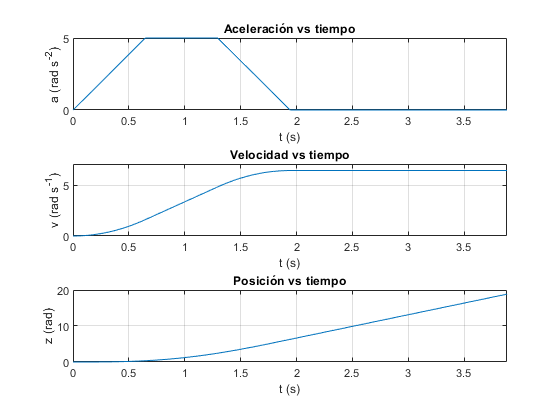

subplot(3,1,1)
plot(ts,aceleracion(ts))
title('Aceleración vs tiempo')
grid on
xlabel('t (s)')
ylabel('a (rad s^{-2})')
xlim([0 double(2*Tgiro)])

subplot(3,1,2)
plot(ts,velocidad(ts))
title('Velocidad vs tiempo')
grid on
xlabel('t (s)')
ylabel('v (rad s^{-1})')
ylim([0 Vmax*1.1])
xlim([0 double(2*Tgiro)])

subplot(3,1,3)
plot(ts,posicion(ts))
title('Posición vs tiempo')
grid on
xlabel('t (s)')
ylabel('z (rad)')
xlim([0 double(2*Tgiro)])


TablaCinematica=table(double(ts)',double(aceleracion(ts))',double(velocidad(ts))',double(posicion(ts))');
TablaCinematica.Properties.VariableNames=["Tiempo","Aceleracion","Velocidad","Posicion"]

TablaCinematica = 1000×4 table
     Tiempo      Aceleracion    Velocidad      Posicion 
    _________    ___________    __________    __________

            0            0               0             0
    0.0038871      0.03003      5.8365e-05    7.5625e-08
    0.0077743      0.06006      0.00023346      6.05e-07
     0.011661      0.09009      0.00052529    2.0419e-06
     0.015549      0.12012      0.00093385      4.84e-06
     0.019436      0.15015       0.0014591    9.4531e-06
     0.023323      0.18018       0.0021012    1.6335e-05
      0.02721      0.21021       0.0028599    2.5939e-05
     0.031097      0.24024       0.0037354     3.872e-05
     0.034984      0.27027       0.0047276    5.5131e-05
     0.038871       0.3003       0.0058365    7.5625e-05
     0.042759      0.33033       0.0070622    0.00010066
     0.046646      0.36036       0

Vr_2 = 0.7500

Vr_3 = 1.7000

Vr_1y = 0.4500

$$Vtheta\_2 = \frac{\pi }{6}$$

Vomega_2 = 20

Valpha_2 = 0

$$Fc(t) = \sin\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)-r_{\mathrm{1y}}$$

$$fc(t) = r_{1}\,\sin\left(\theta_{1}\right)-r_{\mathrm{1y}}$$

$$SolR\_1 = \frac{r_{\mathrm{1y}}}{\sin\left(\theta_{1}\right)}$$

$$Fx(t) = r_{2}\,\cos\left(\Theta_{2}\left(t\right)\right)-\cos\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)+r_{3}\,\cos\left(\Theta_{3}\left(t\right)\right)$$

$$fx = r_{2}\,\cos\left(\theta_{2}\right)+r_{3}\,\cos\left(\theta_{3}\right)-\frac{r_{\mathrm{1y}}\,\cos\left(\theta_{1}\right)}{\sin\left(\theta_{1}\right)}$$

$$fx = r_{2}\,\cos\left(\theta_{2}\right)+r_{3}\,\cos\left(\theta_{3}\right)-r_{\mathrm{1y}}\,\cot\left(\theta_{1}\right)$$

$$SolTheta\_1 = \mathrm{acot}\left(\frac{r_{2}\,\cos\left(\theta_{2}\right)+r_{3}\,\cos\left(\theta_{3}\right)}{r_{\mathrm{1y}}}\right)$$

$$Fy(t) = \sin\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)-r_{3}\,\sin\left(\Theta_{3}\left(t\right)\right)-r_{2}\,\sin\left(\Theta_{2}\left(t\right)\right)$$

$$fy = r_{\mathrm{1y}}-r_{2}\,\sin\left(\theta_{2}\right)-r_{3}\,\sin\left(\theta_{3}\right)$$

$$SolTheta\_3 = \mathrm{asin}\left(\frac{r_{\mathrm{1y}}-r_{2}\,\sin\left(\theta_{2}\right)}{r_{3}}\right)$$

$$F1 = \omega_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-V_{r}\,\cos\left(\theta_{1}\right)-\omega_{2}\,r_{2}\,\sin\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\sin\left(\theta_{3}\right)$$

$$F2 = V_{r}\,\sin\left(\theta_{1}\right)+\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)-\omega_{2}\,r_{2}\,\cos\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\cos\left(\theta_{3}\right)$$

$$F3 = V_{r}\,\sin\left(\theta_{1}\right)+\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)$$

$$D2FcDt2(t) = \sin\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}R_{1}\left(t\right)-\sin\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,{\left(\frac{\partial }{\partial t}\Theta_{1}\left(t\right)\right)}^{2}+\cos\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{1}\left(t\right)+2\,\cos\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\Theta_{1}\left(t\right)\,\frac{\partial }{\partial t}R_{1}\left(t\right)$$

$$D2FxDt2(t) = \cos\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,{\left(\frac{\partial }{\partial t}\Theta_{1}\left(t\right)\right)}^{2}-r_{2}\,\sin\left(\Theta_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{2}\left(t\right)-r_{3}\,\sin\left(\Theta_{3}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{3}\left(t\right)-\cos\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}R_{1}\left(t\right)+\sin\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{1}\left(t\right)+2\,\sin\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\Theta_{1}\left(t\right)\,\frac{\partial }{\partial t}R_{1}\left(t\right)-r_{2}\,\cos\left(\Theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\Theta_{2}\left(t\right)\right)}^{2}-r_{3}\,\cos\left(\Theta_{3}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\Theta_{3}\left(t\right)\right)}^{2}$$

$$D2FyDt2(t) = \sin\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}R_{1}\left(t\right)+r_{2}\,\sin\left(\Theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\Theta_{2}\left(t\right)\right)}^{2}+r_{3}\,\sin\left(\Theta_{3}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\Theta_{3}\left(t\right)\right)}^{2}-r_{2}\,\cos\left(\Theta_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{2}\left(t\right)-r_{3}\,\cos\left(\Theta_{3}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{3}\left(t\right)-\sin\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,{\left(\frac{\partial }{\partial t}\Theta_{1}\left(t\right)\right)}^{2}+\cos\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{1}\left(t\right)+2\,\cos\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\Theta_{1}\left(t\right)\,\frac{\partial }{\partial t}R_{1}\left(t\right)$$

$$F4 = -r_{1}\,\sin\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\cos\left(\theta_{1}\right)\,\omega_{1}+a_{r}\,\sin\left(\theta_{1}\right)+\alpha_{1}\,r_{1}\,\cos\left(\theta_{1}\right)$$

$$F5 = r_{1}\,\cos\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\sin\left(\theta_{1}\right)\,\omega_{1}-r_{2}\,\cos\left(\theta_{2}\right)\,{\omega_{2}}^{2}-r_{3}\,\cos\left(\theta_{3}\right)\,{\omega_{3}}^{2}-a_{r}\,\cos\left(\theta_{1}\right)+\alpha_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-\alpha_{2}\,r_{2}\,\sin\left(\theta_{2}\right)-\alpha_{3}\,r_{3}\,\sin\left(\theta_{3}\right)$$

$$F6 = -r_{1}\,\sin\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\cos\left(\theta_{1}\right)\,\omega_{1}+r_{2}\,\sin\left(\theta_{2}\right)\,{\omega_{2}}^{2}+r_{3}\,\sin\left(\theta_{3}\right)\,{\omega_{3}}^{2}+a_{r}\,\sin\left(\theta_{1}\right)+\alpha_{1}\,r_{1}\,\cos\left(\theta_{1}\right)-\alpha_{2}\,r_{2}\,\cos\left(\theta_{2}\right)-\alpha_{3}\,r_{3}\,\cos\left(\theta_{3}\right)$$

$$f(r\_1, theta\_1, theta\_3, V\_r, omega\_1, omega\_3, a\_r, alpha\_1, alpha\_3) = \begin{array}{l} \left(\begin{array}{c} r_{1}\,\sin\left(\theta_{1}\right)-r_{\mathrm{1y}}\\ r_{2}\,\cos\left(\theta_{2}\right)+r_{3}\,\cos\left(\theta_{3}\right)-r_{\mathrm{1y}}\,\cot\left(\theta_{1}\right)\\ r_{\mathrm{1y}}-r_{2}\,\sin\left(\theta_{2}\right)-r_{3}\,\sin\left(\theta_{3}\right)\\ \omega_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-V_{r}\,\cos\left(\theta_{1}\right)-\omega_{2}\,r_{2}\,\sin\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\sin\left(\theta_{3}\right)\\ V_{r}\,\sin\left(\theta_{1}\right)+\sigma_{3}-\omega_{2}\,r_{2}\,\cos\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\cos\left(\theta_{3}\right)\\ V_{r}\,\sin\left(\theta_{1}\right)+\sigma_{3}\\ -\sigma_{1}+\sigma_{2}+a_{r}\,\sin\left(\theta_{1}\right)+\sigma_{4}\\ r_{1}\,\cos\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\sin\left(\theta_{1}\right)\,\omega_{1}-r_{2}\,\cos\left(\theta_{2}\right)\,{\omega_{2}}^{2}-r_{3}\,\cos\left(\theta_{3}\right)\,{\omega_{3}}^{2}-a_{r}\,\cos\left(\theta_{1}\right)+\alpha_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-\alpha_{2}\,r_{2}\,\sin\left(\theta_{2}\right)-\alpha_{3}\,r_{3}\,\sin\left(\theta_{3}\right)\\ -\sigma_{1}+\sigma_{2}+r_{2}\,\sin\left(\theta_{2}\right)\,{\omega_{2}}^{2}+r_{3}\,\sin\left(\theta_{3}\right)\,{\omega_{3}}^{2}+a_{r}\,\sin\left(\theta_{1}\right)+\sigma_{4}-\alpha_{2}\,r_{2}\,\cos\left(\theta_{2}\right)-\alpha_{3}\,r_{3}\,\cos\left(\theta_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=r_{1}\,\sin\left(\theta_{1}\right)\,{\omega_{1}}^{2}\\ \sigma_{2}=2\,V_{r}\,\cos\left(\theta_{1}\right)\,\omega_{1}\\ \sigma_{3}=\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)\\ \sigma_{4}=\alpha_{1}\,r_{1}\,\cos\left(\theta_{1}\right) \end{array}$$

$$f(r\_1, theta\_1, theta\_3, V\_r, omega\_1, omega\_3, a\_r, alpha\_1, alpha\_3) = \begin{array}{l} \left(\begin{array}{c} r_{1}\,\sin\left(\theta_{1}\right)-\frac{9}{20}\\ \frac{17\,\cos\left(\theta_{3}\right)}{10}-\frac{9\,\cot\left(\theta_{1}\right)}{20}+\frac{3\,\sqrt{3}}{8}\\ \frac{3}{40}-\frac{17\,\sin\left(\theta_{3}\right)}{10}\\ \omega_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-\frac{17\,\omega_{3}\,\sin\left(\theta_{3}\right)}{10}-V_{r}\,\cos\left(\theta_{1}\right)-\frac{15}{2}\\ V_{r}\,\sin\left(\theta_{1}\right)-\frac{15\,\sqrt{3}}{2}-\frac{17\,\omega_{3}\,\cos\left(\theta_{3}\right)}{10}+\sigma_{3}\\ V_{r}\,\sin\left(\theta_{1}\right)+\sigma_{3}\\ -\sigma_{1}+\sigma_{2}+a_{r}\,\sin\left(\theta_{1}\right)+\sigma_{4}\\ r_{1}\,\cos\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\sin\left(\theta_{1}\right)\,\omega_{1}-\frac{17\,\cos\left(\theta_{3}\right)\,{\omega_{3}}^{2}}{10}-150\,\sqrt{3}-a_{r}\,\cos\left(\theta_{1}\right)-\frac{17\,\alpha_{3}\,\sin\left(\theta_{3}\right)}{10}+\alpha_{1}\,r_{1}\,\sin\left(\theta_{1}\right)\\ -\sigma_{1}+\sigma_{2}+\frac{17\,\sin\left(\theta_{3}\right)\,{\omega_{3}}^{2}}{10}-\frac{17\,\alpha_{3}\,\cos\left(\theta_{3}\right)}{10}+a_{r}\,\sin\left(\theta_{1}\right)+\sigma_{4}+150 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=r_{1}\,\sin\left(\theta_{1}\right)\,{\omega_{1}}^{2}\\ \sigma_{2}=2\,V_{r}\,\cos\left(\theta_{1}\right)\,\omega_{1}\\ \sigma_{3}=\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)\\ \sigma_{4}=\alpha_{1}\,r_{1}\,\cos\left(\theta_{1}\right) \end{array}$$

$$f(r\_1, theta\_1, theta\_3, V\_r, omega\_1, omega\_3, a\_r, alpha\_1, alpha\_3) = \begin{array}{l} \left(\begin{array}{c} r_{1}\,\sin\left(\theta_{1}\right)-\frac{9}{20}\\ \frac{17\,\cos\left(\theta_{3}\right)}{10}-\frac{9\,\cot\left(\theta_{1}\right)}{20}+\frac{3\,\sqrt{3}}{8}\\ \frac{3}{40}-\frac{17\,\sin\left(\theta_{3}\right)}{10}\\ \omega_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-\frac{17\,\omega_{3}\,\sin\left(\theta_{3}\right)}{10}-V_{r}\,\cos\left(\theta_{1}\right)-\frac{15}{2}\\ V_{r}\,\sin\left(\theta_{1}\right)-\frac{15\,\sqrt{3}}{2}-\frac{17\,\omega_{3}\,\cos\left(\theta_{3}\right)}{10}+\sigma_{3}\\ V_{r}\,\sin\left(\theta_{1}\right)+\sigma_{3}\\ -\sigma_{1}+\sigma_{2}+a_{r}\,\sin\left(\theta_{1}\right)+\sigma_{4}\\ r_{1}\,\cos\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\sin\left(\theta_{1}\right)\,\omega_{1}-\frac{17\,\cos\left(\theta_{3}\right)\,{\omega_{3}}^{2}}{10}-150\,\sqrt{3}-a_{r}\,\cos\left(\theta_{1}\right)-\frac{17\,\alpha_{3}\,\sin\left(\theta_{3}\right)}{10}+\alpha_{1}\,r_{1}\,\sin\left(\theta_{1}\right)\\ -\sigma_{1}+\sigma_{2}+\frac{17\,\sin\left(\theta_{3}\right)\,{\omega_{3}}^{2}}{10}-\frac{17\,\alpha_{3}\,\cos\left(\theta_{3}\right)}{10}+a_{r}\,\sin\left(\theta_{1}\right)+\sigma_{4}+150 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=r_{1}\,\sin\left(\theta_{1}\right)\,{\omega_{1}}^{2}\\ \sigma_{2}=2\,V_{r}\,\cos\left(\theta_{1}\right)\,\omega_{1}\\ \sigma_{3}=\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)\\ \sigma_{4}=\alpha_{1}\,r_{1}\,\cos\left(\theta_{1}\right) \end{array}$$

ValoresNR =     2.0000    0.1000    0.1000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000
    3.5652    0.1473    0.0440   -5.2169   -3.7457   -7.7079 -182.4229   71.9543   77.0083
    2.2782    0.1801    0.0441   -7.2894   -1.0190   -7.6488 -393.1789   35.8392   90.9048
    2.4019    0.1889    0.0441   -6.8349    0.6281   -7.6488 -364.3695   32.7881   90.9049
    2.3906    0.1894    0.0441   -6.8024    0.5458   -7.6488 -358.7491   31.9270   90.9049
    2.3906    0.1894    0.0441   -6.8025    0.5454   -7.6488 -358.7333   31.9219   90.9049
    2.3906    0.1894    0.0441   -6.8025    0.5454   -7.6488 -358.7333   31.9219   90.9049


ans =   212.4623
  214.3103
   29.0211
    5.6866
    0.0166
    0.0000


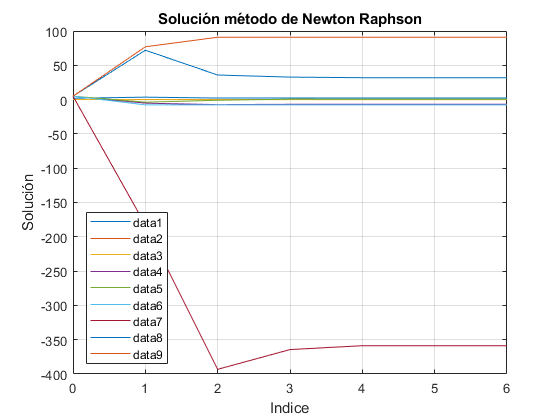

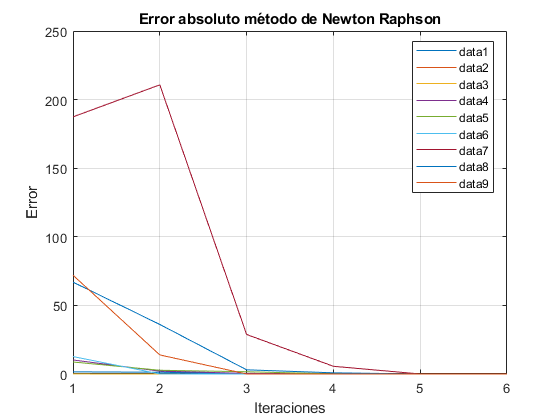

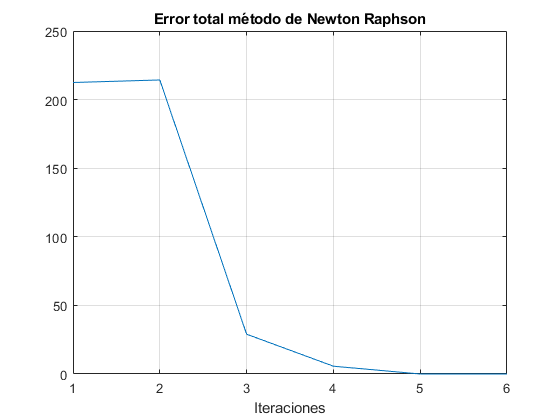

SolNR =     2.3906
    0.1894
    0.0441
   -6.8025
    0.5454
   -7.6488
 -358.7333
   31.9219
   90.9049


ErrorNRFinal = 3.6567e-07

writetable(TablaCinematica,'Perfil_cinematica.txt','delimiter',' ', 'WriteVariableNames', true)
TablaTXT=table(double(ts)',double(velocidad(ts)*180/pi)');
writetable(TablaTXT,'Perfil_Velocidad.txt','delimiter',' ', 'WriteVariableNames', false)
clearvars -except Tgiro posicion aceleracion velocidad TablaCinematica